# **Dimensionality reduction on Ca2+ signal**

s = settings;
s.matlab.editor.AllowFigureAnimation.PersonalValue = true;

## Load experiment

% note : the experiment loaded here has been preprocessed for peak detection and
% rescaling. If this is not the case, you need to do it.
load('C:\Users\THE BEASTWO\Documents\MATLAB\arboreal_scans_final_new_zscored_compressed\2019-10-01_exp_1\2019-10-01_exp_1.mat');


	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 


obj.filter_win = [10, 0];


# 1. PCA

## Example 1.1 : Run PCA

Default method : PCA on rescaled traces. using all timepoints, and auto estimating the number of components to get 90% od the explained variance

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

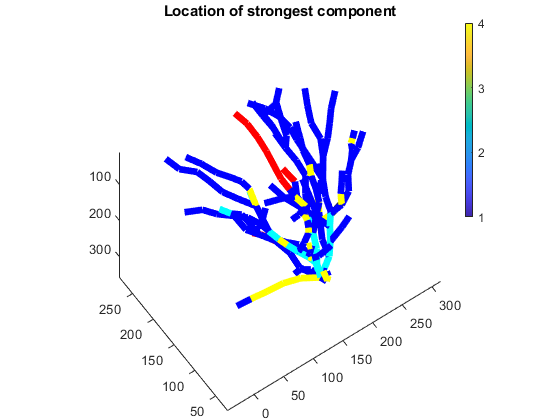

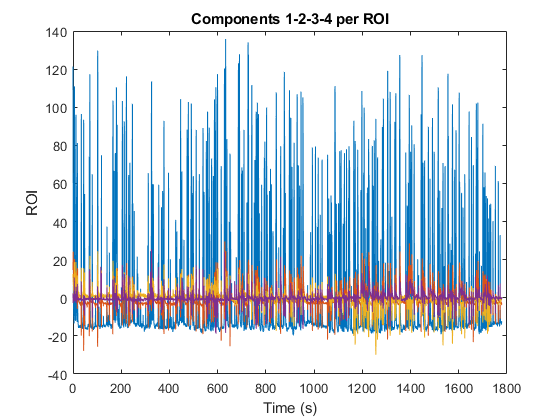

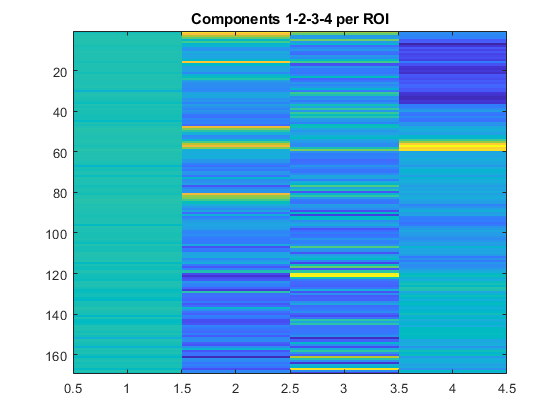

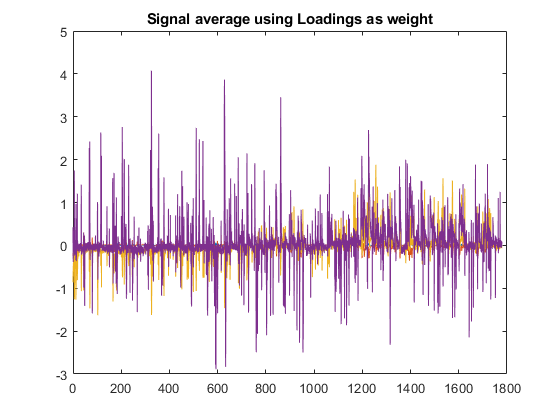

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

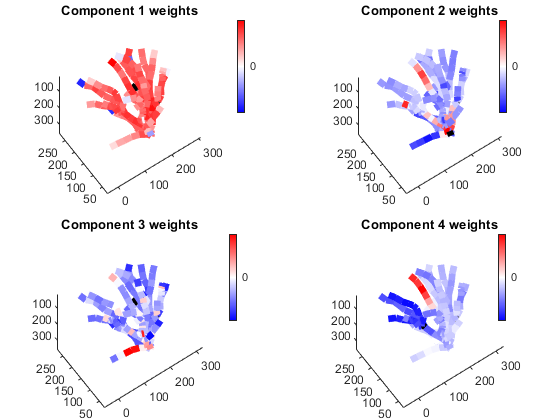

ans = 1×44 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


ans =     0.0633    0.0594    0.0528    0.0473    0.0437    0.0396    0.0347    0.0296    0.0247    0.0202    0.0171    0.0147    0.0124    0.0109    0.0092    0.0077    0.0068    0.0060    0.0054    0.0051    0.0048    0.0045    0.0043    0.0041    0.0039    0.0038    0.0036    0.0033    0.0030    0.0030    0.0029    0.0028    0.0027    0.0027    0.0027    0.0025    0.0023    0.0023    0.0022    0.0020    0.0017    0.0016    0.0032    0.0075    0.0146    0.0227    0.0301    0.0367    0.0434    0.0503
   -0.1931   -0.2393   -0.2517   -0.2733   -0.2799   -0.2983   -0.3060   -0.3045   -0.2950   -0.2759   -0.2666   -0.2436   -0.2246   -0.2172   -0.2061   -0.1928   -0.1748   -0.1585   -0.1520   -0.1514   -0.1460   -0.1303   -0.1290   -0.1197   -0.1183   -0.1160   -0.1108   -0.0984   -0.0886   -0.0861   -0.0813   -0.0764   -0.0749   -0.0741   -0.0715   -0.0656   -0.0587   -0.0570   -0.0598   -0.0648   -0.0665   -0.0620   -0.0562   -0.0598   -0.0622   -0.0592   -0.0538   -0.0392   -0.0521   

obj.get_dimensionality()

## Example 1.2 : Run PCA on rescaled traces and set number of components

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

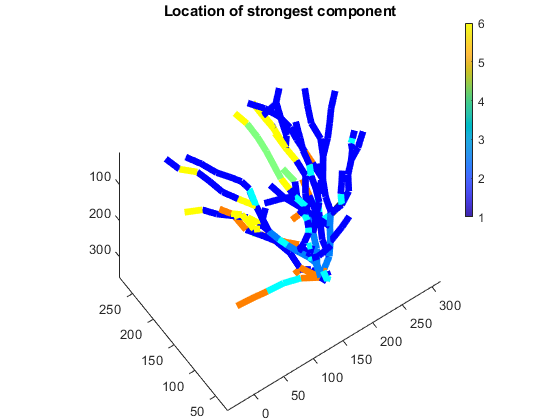

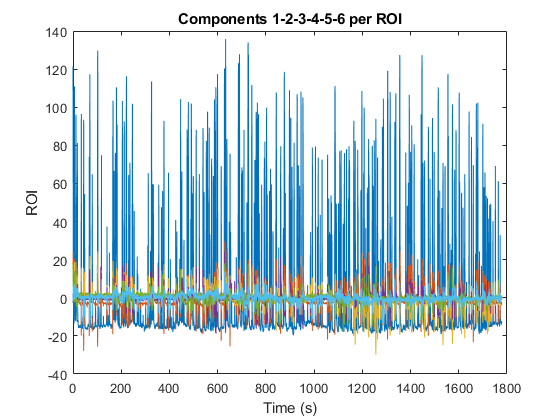

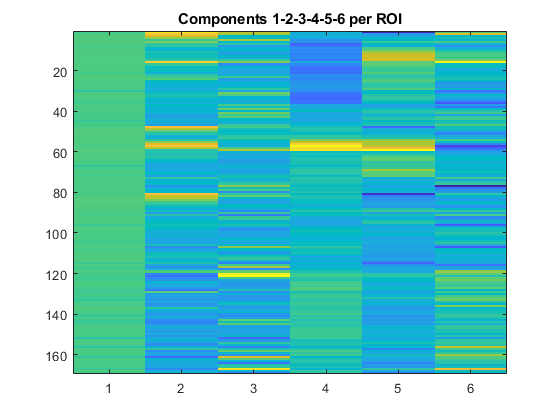

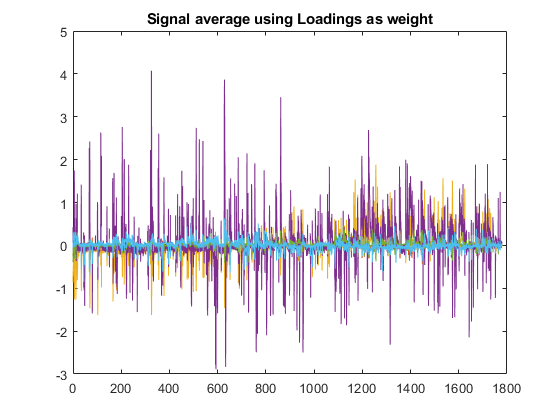

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

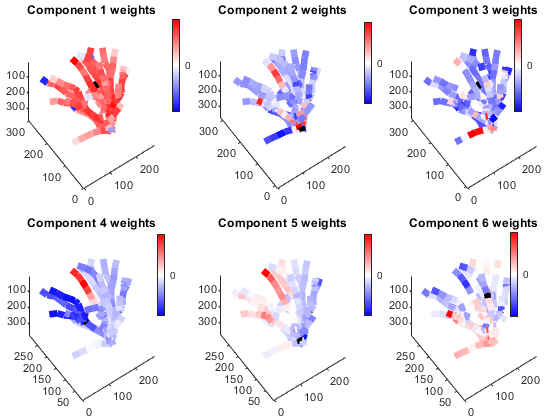

ans = 1×44 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


% Selecting first 6 components
obj.get_dimensionality(obj.rescaled_traces,'pca','',6); 

Note : obj.rescaled_trace and 'pca' are the default values, you don't actually have to set them

# 1. Timepoint Selection

The 4th input controls the timepoints that will be used. It can be the global events, some behavioural metrics or any arbitrary set of timepoints. See obj.get_tp_for_condition for more information

## Example 2.1 : Run PCA on rescaled peaks (not the whole traces)

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

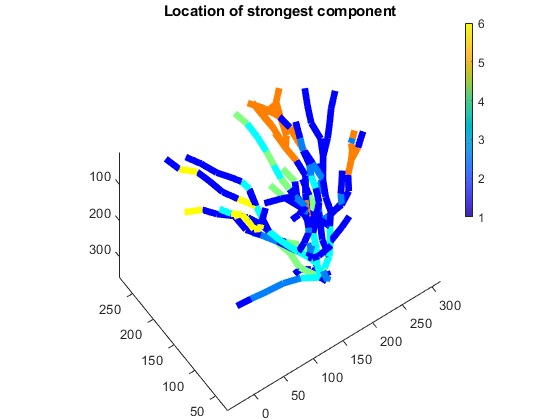

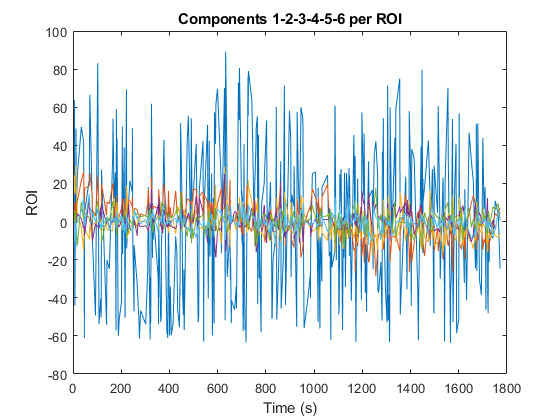

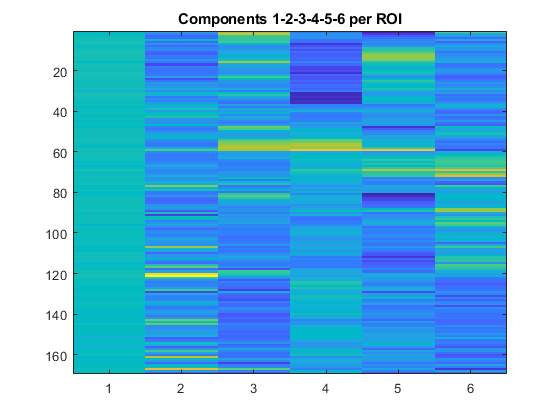

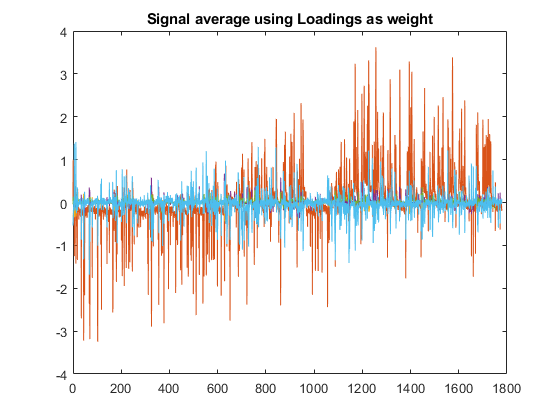

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

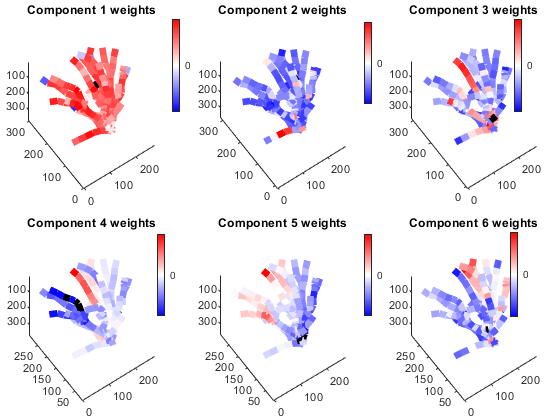

ans = 1×44 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


obj.get_dimensionality(obj.rescaled_traces,'pca','peaks',6);

## Example 2.2 : Run PCA on median subtracted rescaled peaks 

Adding the subtracted flag wil lremove the signal median. This is likely to affect strongly the first Principal component in neurons presenting global events.

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

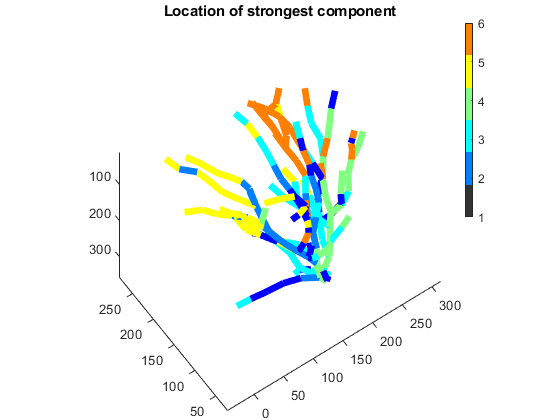

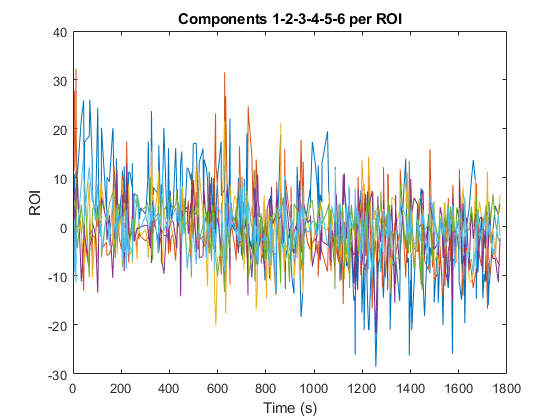

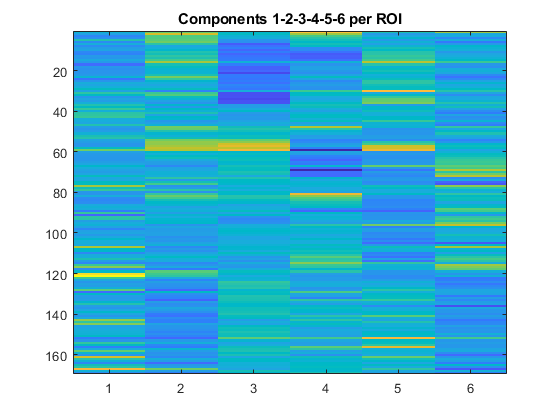

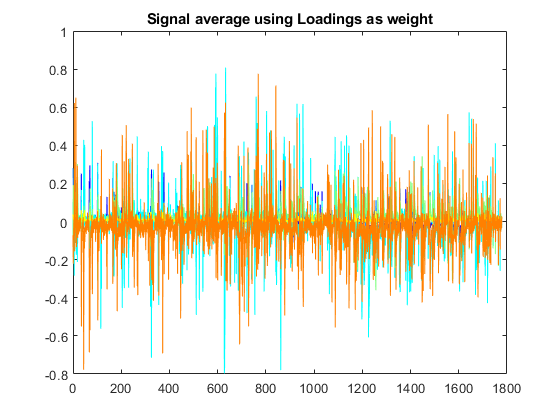

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

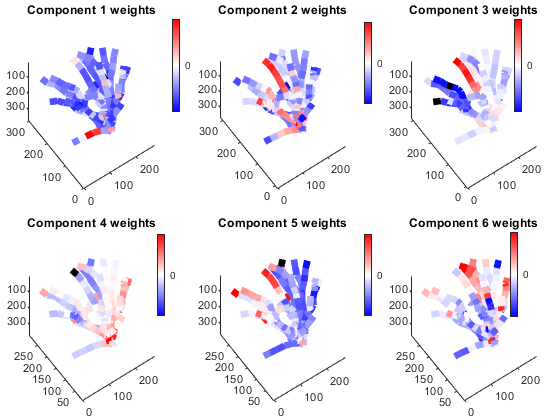

ans = 1×44 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


obj.get_dimensionality(obj.rescaled_traces,'pca','peaks_subtracted',6);

## Example 2.3 : Run PCA on median subtracted rescaled peaks during running only

You need to add the name of the behaviour to filter. Names can be obtained using obj.behaviour.types

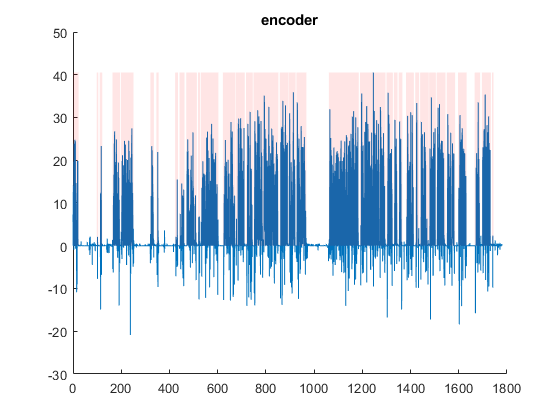

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

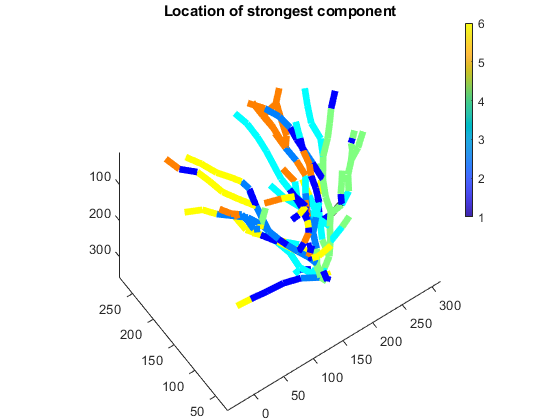

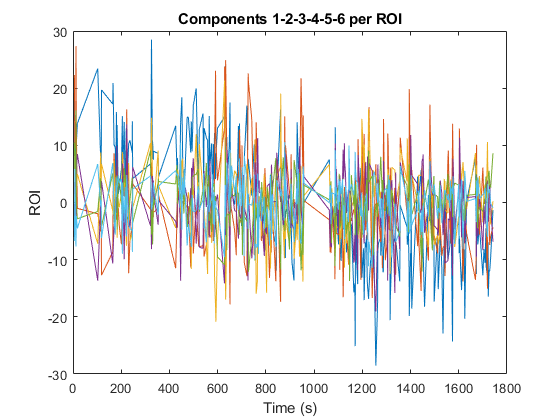

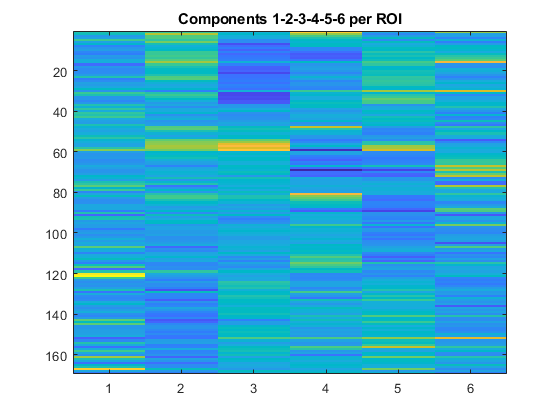

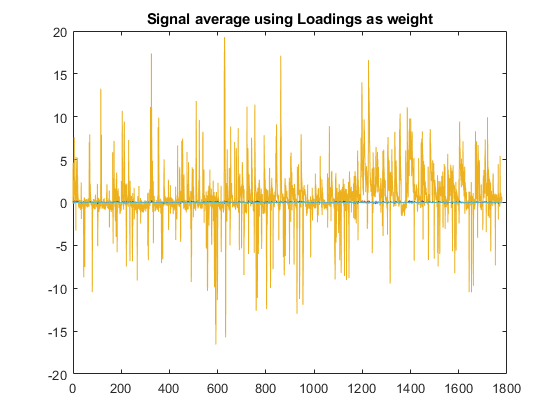

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

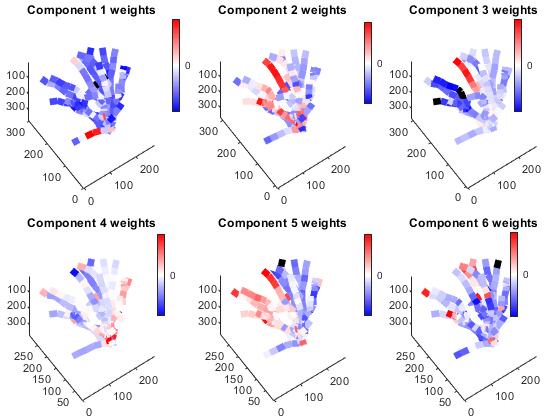

ans = 1×44 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


obj.get_dimensionality(obj.rescaled_traces,'pca','peaks_subtracted_encoder',6);

## Example 2.4 : Run PCA on median subtracted rescaled peaks while NOT running only

This correspond to the opposite set of timepoints compared to the previous section

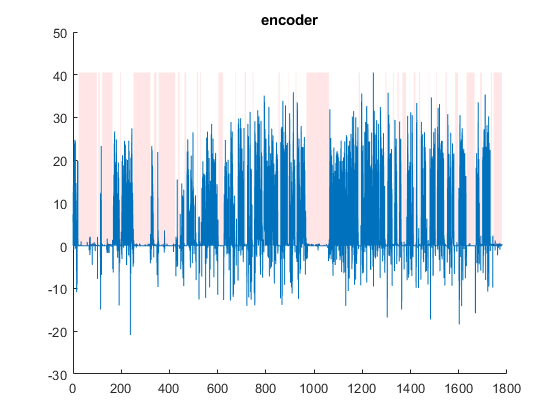

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

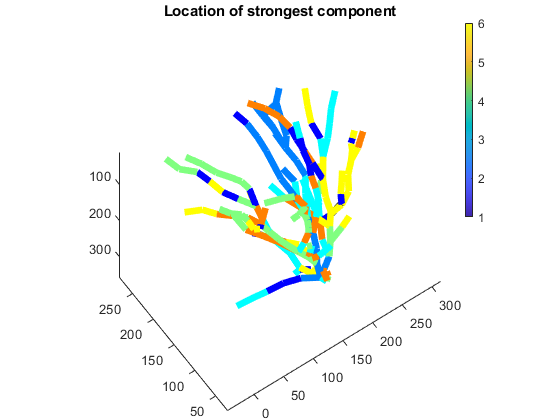

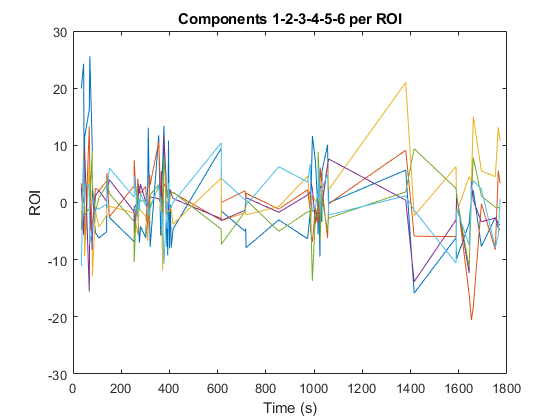

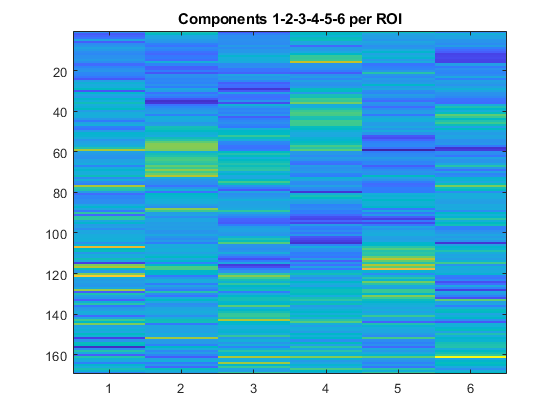

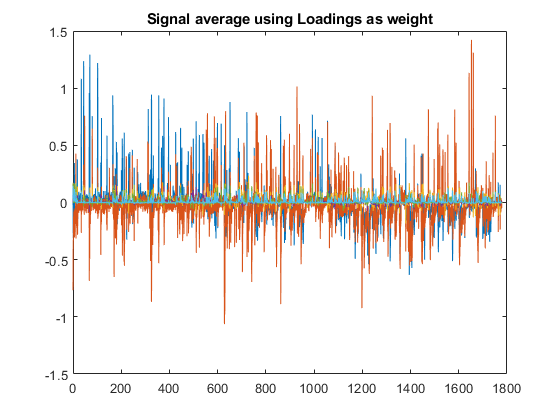

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

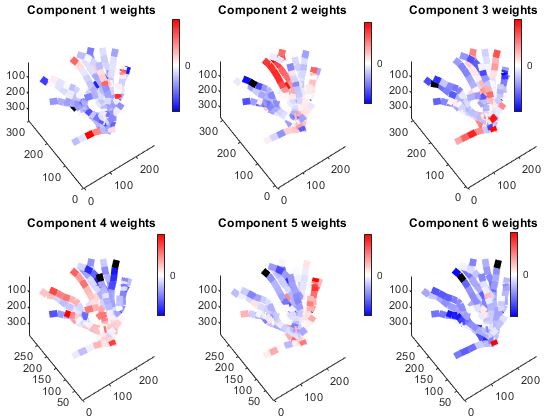

ans = 1×44 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


obj.get_dimensionality(obj.rescaled_traces,'pca','peaks_subtracted_~encoder',6);

## Example 2.4 : Adjust behaviour smoothing and detrending

Smoothing can be very noisy. We'll match the smoothing to the calcium imaging smoothing. We'll also activate behaviour detrending to compensate for artefacts in Motion indices

Note that in this example, we use "whisker" which is not an exact match to one of the behaviour type. Consequently, all the matching values are selected.

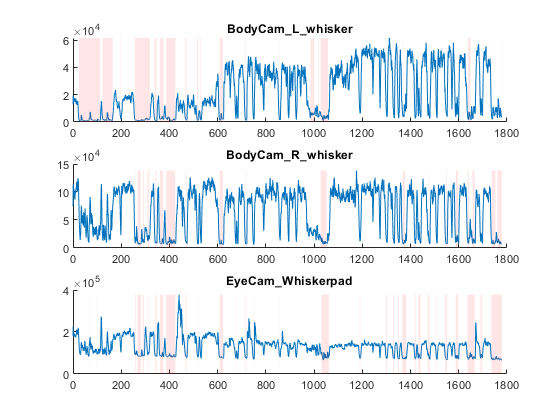

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

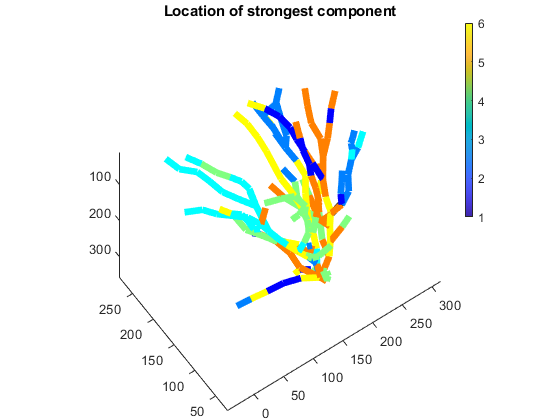

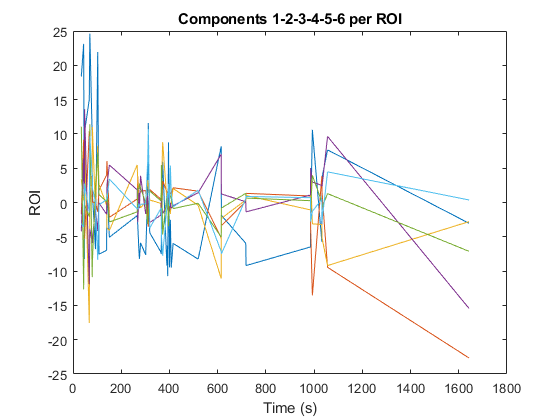

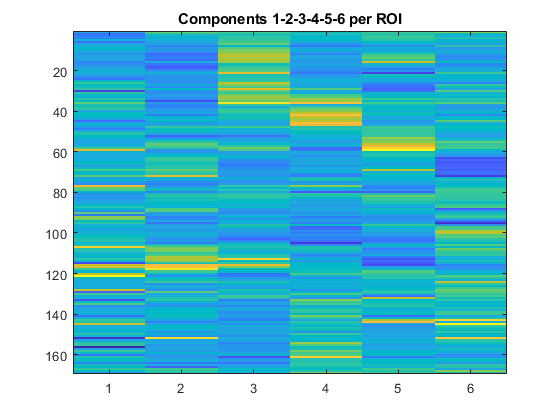

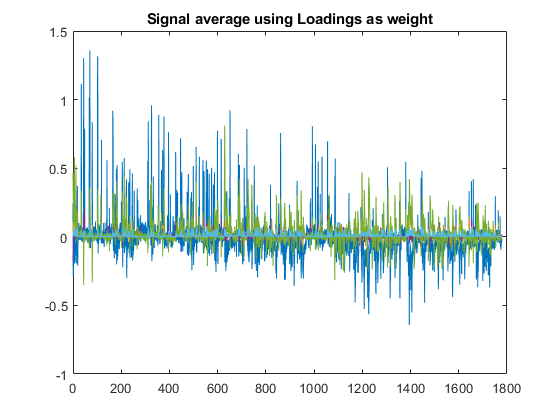

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

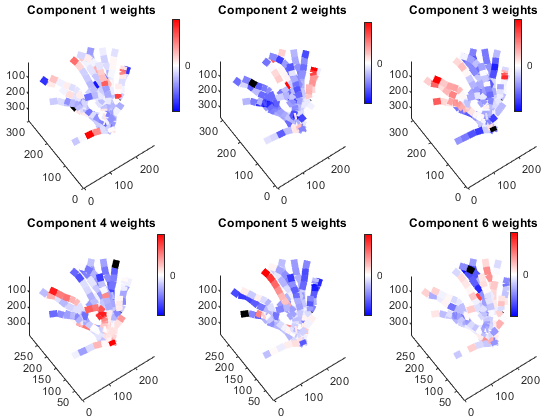

ans = 1×44 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


obj.beh_smoothing = obj.filter_win * 10;
obj.detrend_behaviour = 1;
obj.get_dimensionality(obj.rescaled_traces,'pca','peaks_subtracted_~whisker',6);

## Example 2.5 : Add a tail to behaviour timepoints

If you want to include movement onset for example, add a preceding windo to the "on" behaviour

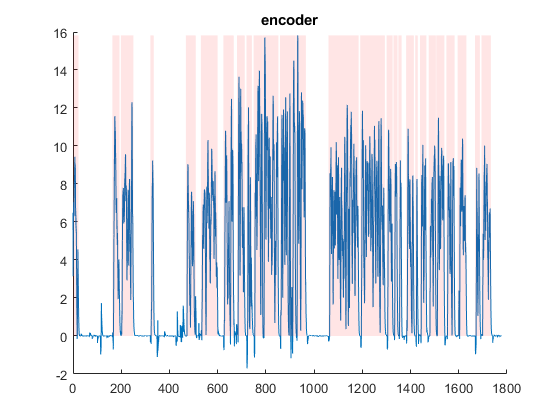

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

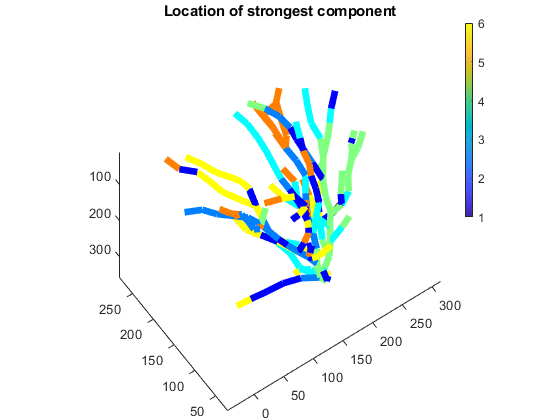

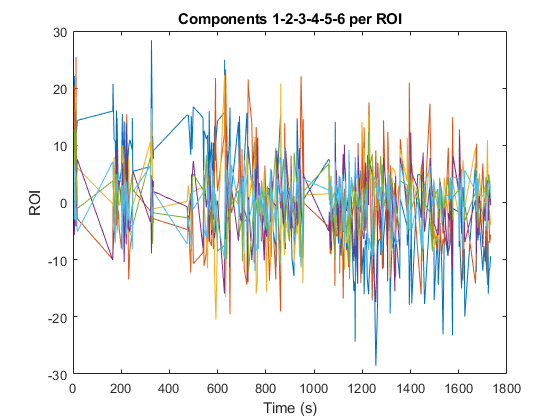

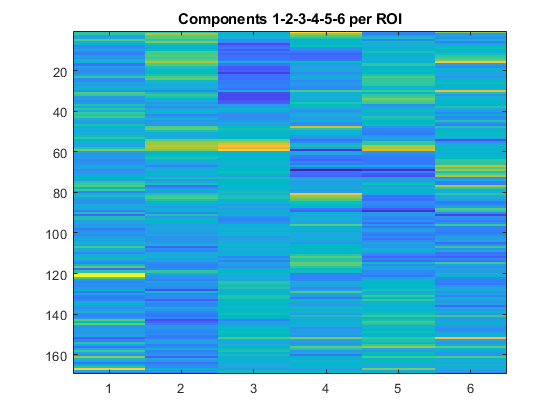

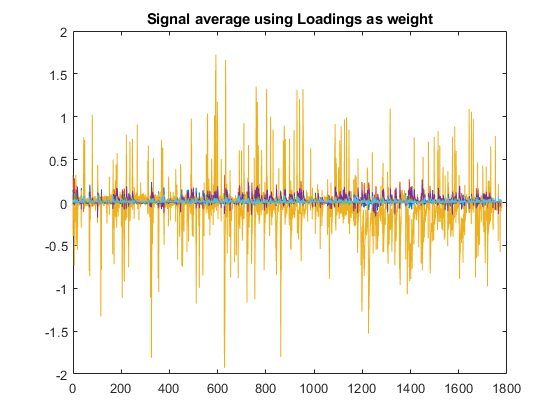

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

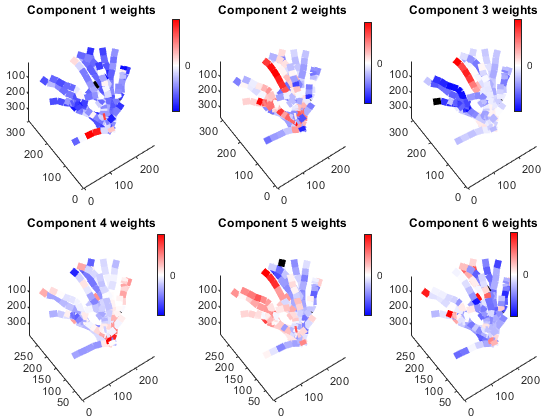

ans = 1×44 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


obj.get_dimensionality(obj.rescaled_traces,'pca','peaks_subtracted_encoder[5, 0]',6); % add 5 sec before the behaviour

# 3. Factor Analysis

## Example 3.1 : Run Factoran on rescaled traces and set number of components

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

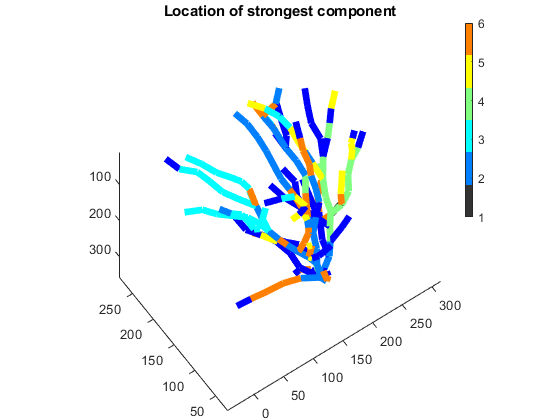

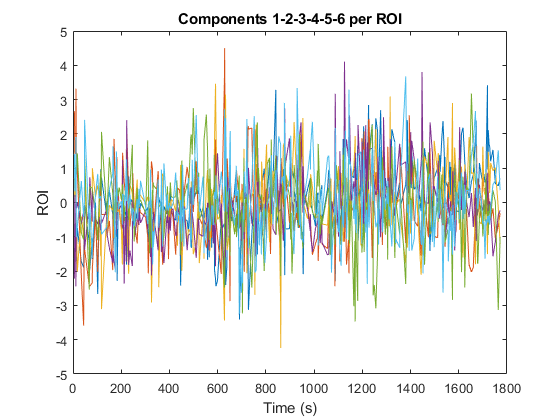

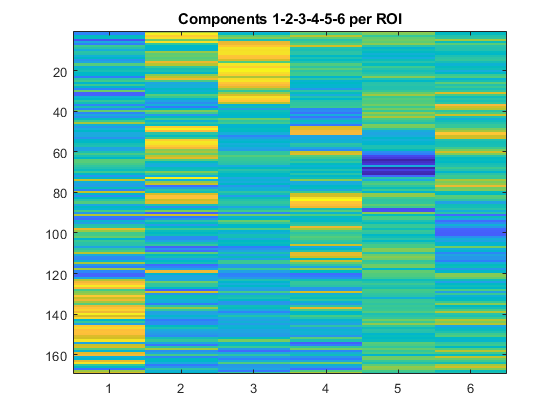

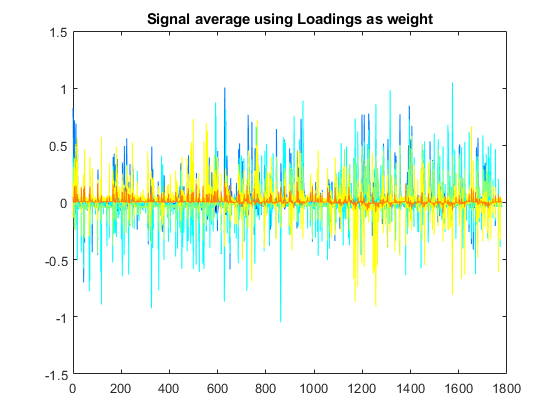

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

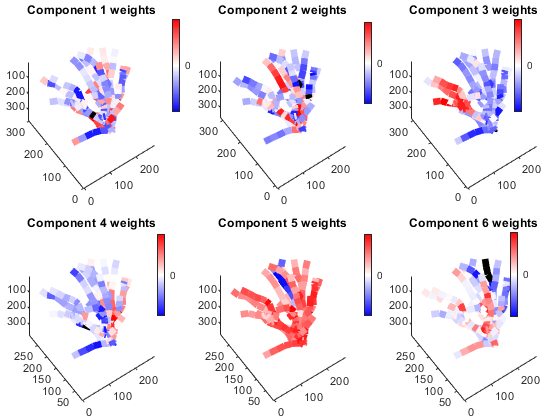

ans = 1×44 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


% Selecting first 6 Factors
obj.get_dimensionality(obj.rescaled_traces,'factoran','peaks_subtracted',6);

Note : if you don't specify the number of factor, it is set as the number of PCA compnenents explaining 90% of the variance

# 4. NNMF

## Example 4.1 : Run NNMF on rescaled traces and set number of components

N_REPLICATES = 20

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

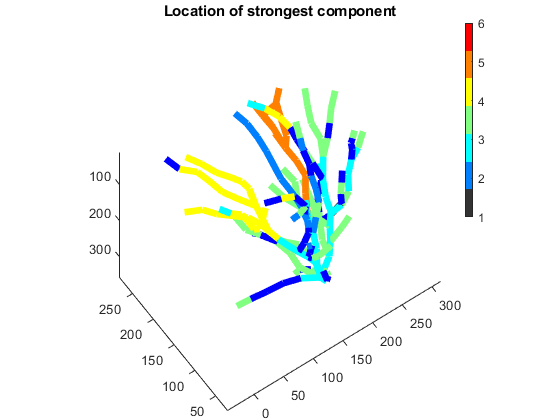

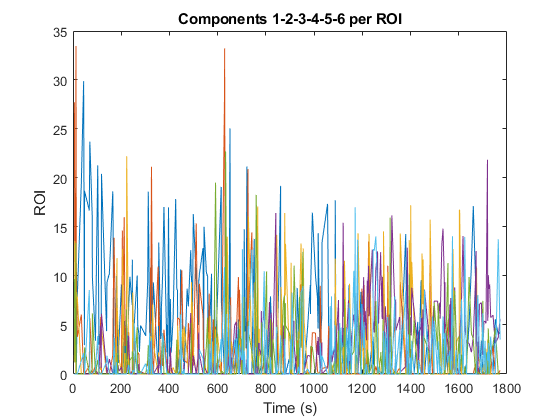

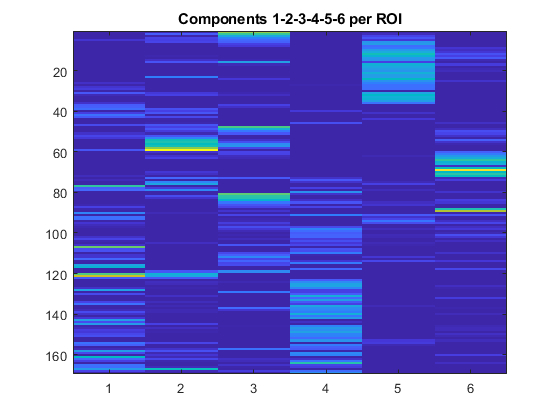

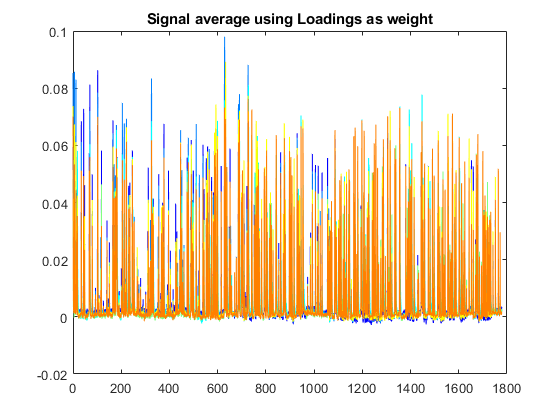

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

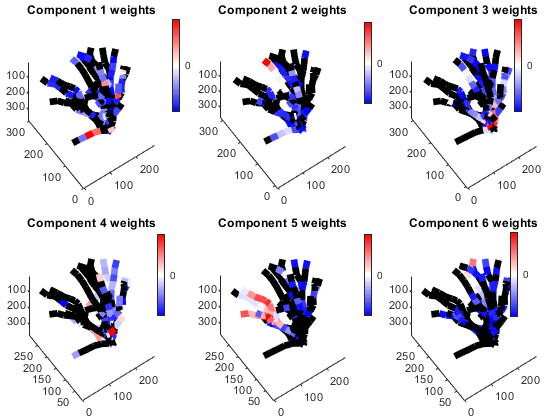

ans = 1×44 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


% Selecting first 6 Componenets
obj.get_dimensionality(obj.rescaled_traces,'nnmf','peaks_subtracted',6);

Note : NNMF will not capture negative modulation

# 5. PHATE

## Example 5.1 : Run PHATE on rescaled traces and set number of components

Doing PCA
PCA using random SVD
PCA took 0.013652 seconds
using alpha decaying kernel
Computing alpha decay kernel:
Number of samples = 169
First iteration: k = 100
Number of samples below the threshold from 1st iter: 169
   Symmetrize affinities
   Done computing kernel
Computing kernel took 0.041913 seconds
Make kernel row stochastic
Running PHATE without landmarking
Finding optimal t using VNE
VNE optimal t = 24


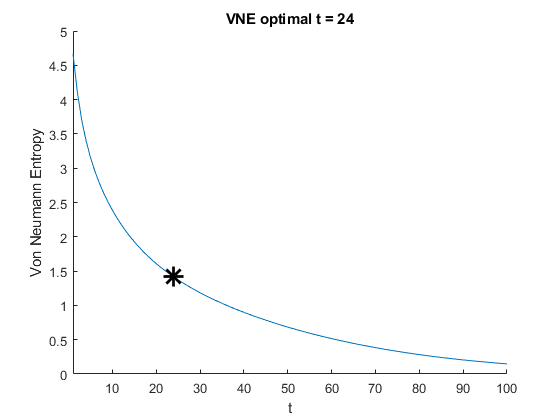

Diffusing operator
Diffusion took 0.0067248 seconds
Computing potential distances
using -log(P) potential distance
Computing potential distance took 0.0071517 seconds
Doing classical MDS
CMDS took 0.0059574 seconds
Doing metric MDS:

                     Stress          Norm of         Norm of     Line Search
   Iteration       Criterion        Gradient           Step       Iterations
  ---------------------------------------------------------------------------
           0        0.974293       0.0109876
           1        0.209811      0.00728623         48.9301              10
           2        0.162931      0.00767477         11.2034               9
           3         0.10006      0.00726705         9.40957              11
           4       0.0617028      0.00747856         6.35062              10
           5       0.0401324      0.00738145         4.24212               9
           6       0.0278982       0.0068727         2.22704               9
           7       0.019181

tree_aspect = 'simple'

ans = 1

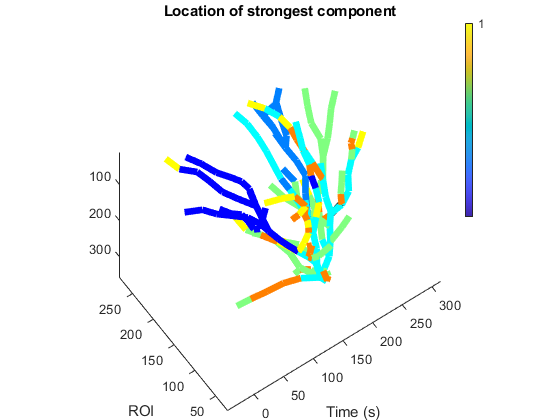

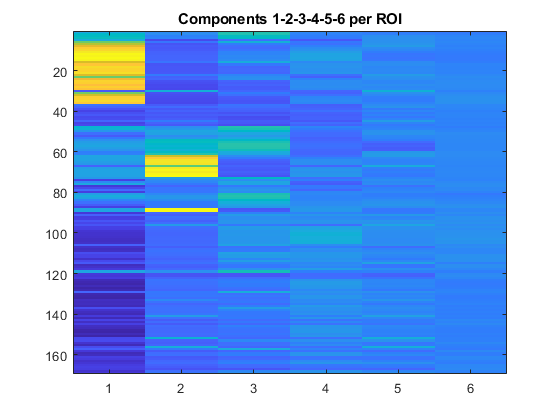

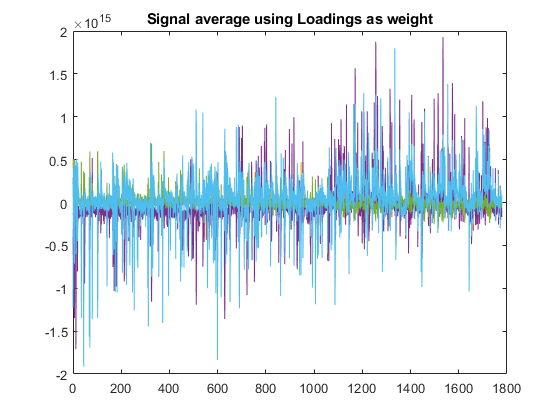

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

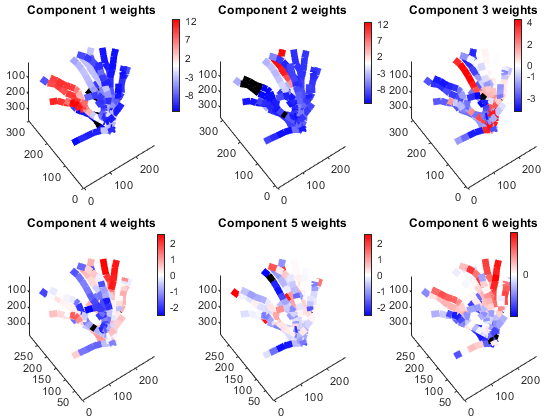

ans = 1×44 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


% Selecting first 6 Componenets
obj.get_dimensionality(obj.rescaled_traces,'phate','peaks_subtracted',6);

# 6. Clustering

## Example 6.1 : Run kmeans clustering

Optimal number of clusters is 3


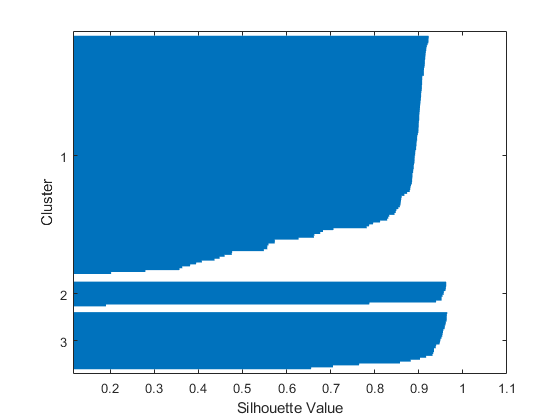

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

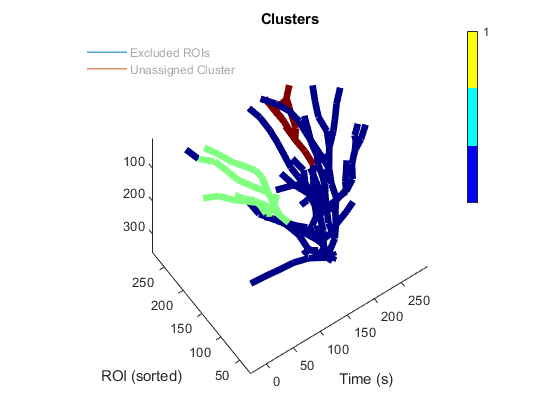

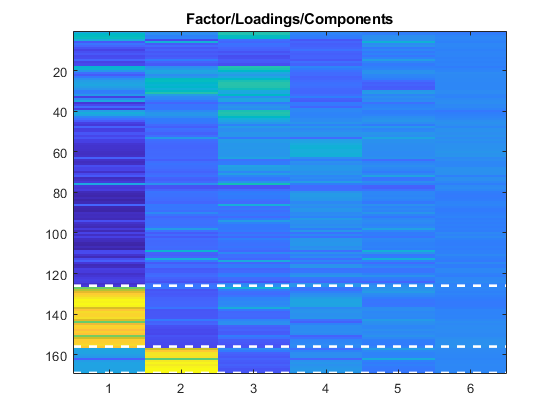

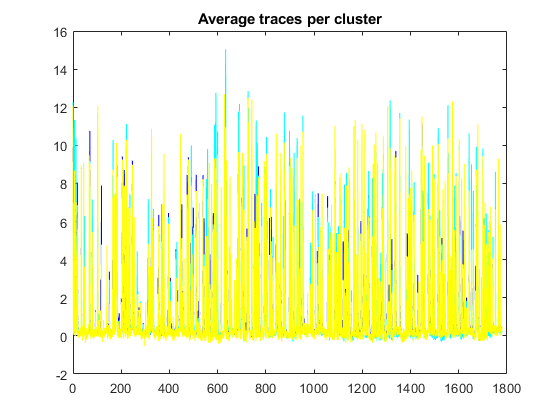

% Use kmeans with auto selection of the number of clusters
obj.cluster_factors('kmeans', []);

## Example 6.2 : Run kmeans clustering and force the number of clusters

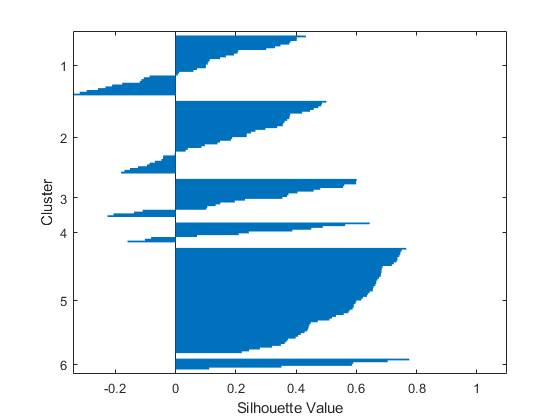

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

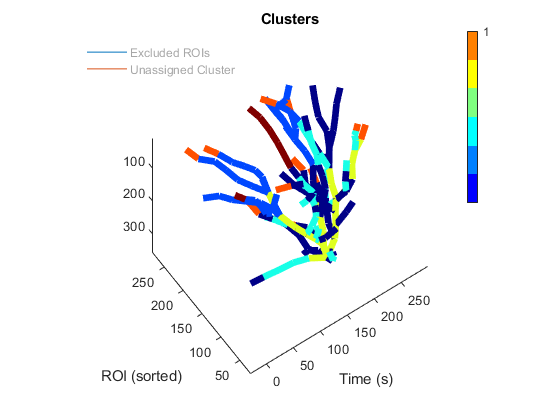

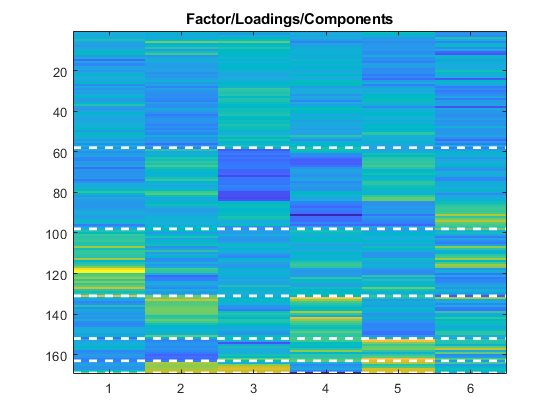

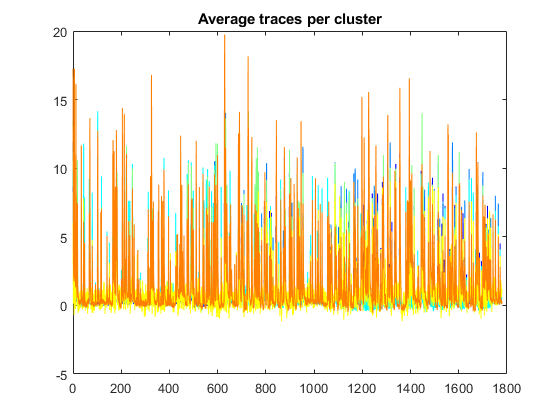

% Set 6 clusters
obj.cluster_factors('kmeans', 6);

## Example 6.3 : Run hierarchical clustering and force the number of clusters

Optimal number of clusters is 3


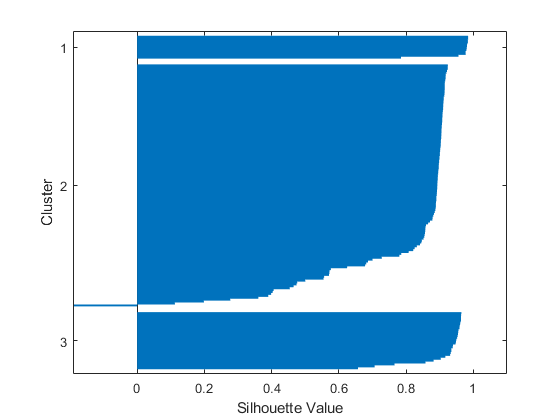

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

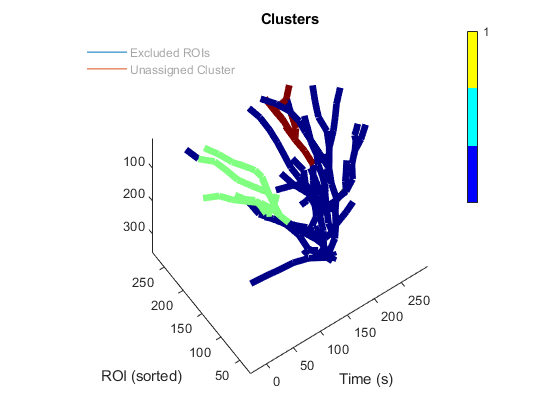

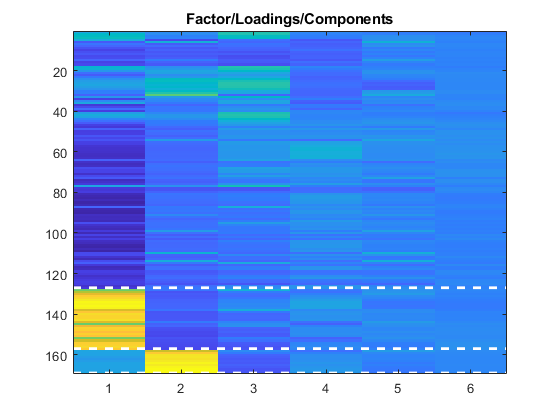

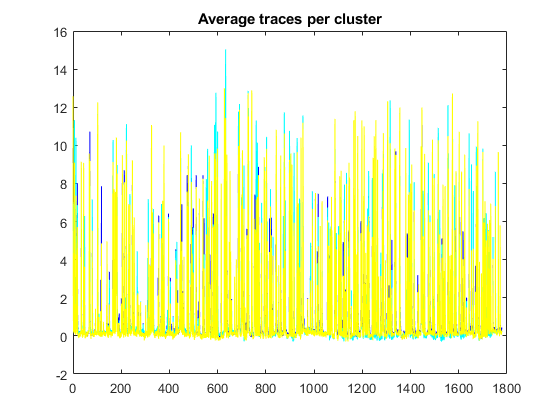

% Use hierarchical with auto selection of the number of clusters
obj.cluster_factors('hierarchical', []);

## Example 6.4 : Run DBscan clustering with automated number of clusters

method = 'dbscan'

rendering = logical
   0


MIN_CLUSTER_SIZE = 4

testing epsilon = 0.1
testing epsilon = 0.10475
testing epsilon = 0.10972
testing epsilon = 0.11492
testing epsilon = 0.12038
testing epsilon = 0.12609
testing epsilon = 0.13207
testing epsilon = 0.13834
testing epsilon = 0.1449
testing epsilon = 0.15178
testing epsilon = 0.15898
testing epsilon = 0.16652
testing epsilon = 0.17443
testing epsilon = 0.1827
testing epsilon = 0.19137
testing epsilon = 0.20045
testing epsilon = 0.20997
testing epsilon = 0.21993
testing epsilon = 0.23036
testing epsilon = 0.2413
testing epsilon = 0.25275
testing epsilon = 0.26474
testing epsilon = 0.2773
testing epsilon = 0.29046
testing epsilon = 0.30424
testing epsilon = 0.31868
testing epsilon = 0.3338
testing epsilon = 0.34964
testing epsilon = 0.36623
testing epsilon = 0.38361
testing epsilon = 0.40182
testing epsilon = 0.42088
testing epsilon = 0.44085
testing epsilon = 0.46177
testing epsilon = 0.48369
testing epsilon = 0.50664
testing epsilon = 0.53068
testing epsilon = 0.55586
testing epsilon = 0.5

MIN_GP = 4

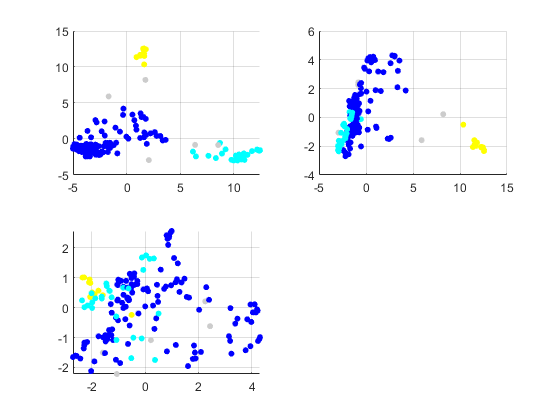

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

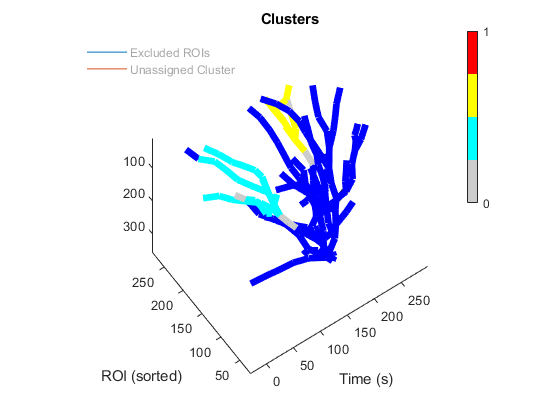

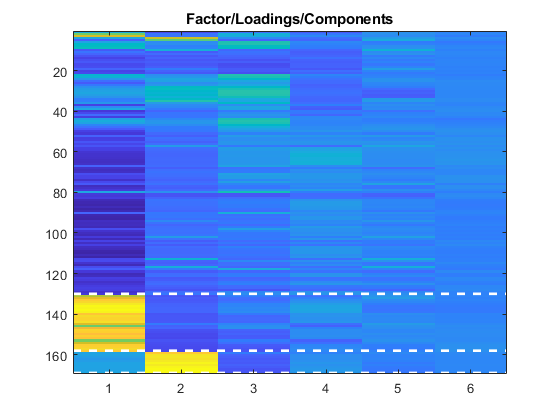

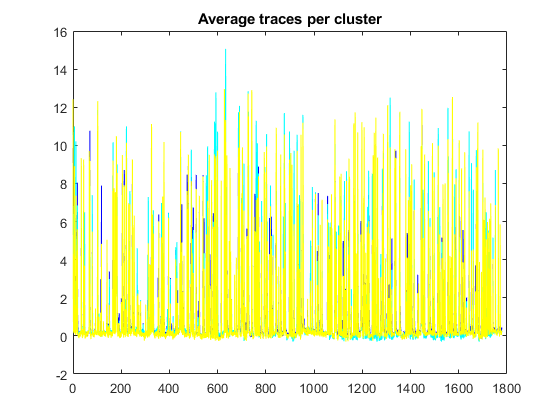

% Use DBscan with auto selection of the number of clusters
obj.cluster_factors('dbscan', []);

## Example 6.5 : Run DBscan clustering and set epsilon

MIN_GP = 4

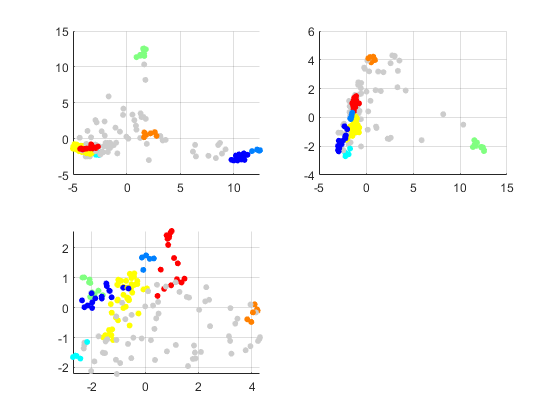

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

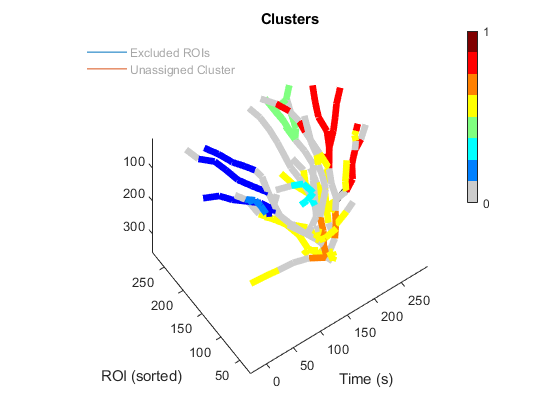

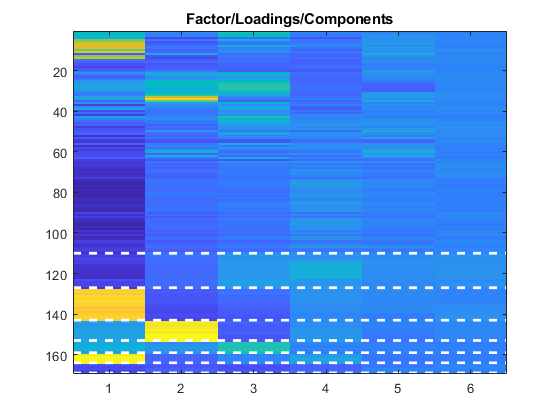

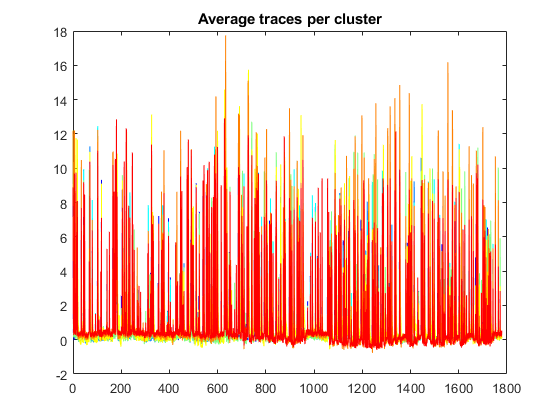

% The second input controls epsilon for dbscan methold
obj.cluster_factors('dbscan', 0.8);

## Example 6.5 : Run DBscan clustering and try to set the number of cluster manually

Witg this method, the algorithm will try to set the optimal epislon value allowing the specified number of clusters. Use a negative value to indicate you don't want epislon

method = 'dbscan'

rendering = logical
   0


MIN_CLUSTER_SIZE = 4

testing epsilon = 0.1
testing epsilon = 0.10475
testing epsilon = 0.10972
testing epsilon = 0.11492
testing epsilon = 0.12038
testing epsilon = 0.12609
testing epsilon = 0.13207
testing epsilon = 0.13834
testing epsilon = 0.1449
testing epsilon = 0.15178
testing epsilon = 0.15898
testing epsilon = 0.16652
testing epsilon = 0.17443
testing epsilon = 0.1827
testing epsilon = 0.19137
testing epsilon = 0.20045
testing epsilon = 0.20997
testing epsilon = 0.21993
testing epsilon = 0.23036
testing epsilon = 0.2413
testing epsilon = 0.25275
testing epsilon = 0.26474
testing epsilon = 0.2773
testing epsilon = 0.29046
testing epsilon = 0.30424
testing epsilon = 0.31868
testing epsilon = 0.3338
testing epsilon = 0.34964
testing epsilon = 0.36623
testing epsilon = 0.38361
testing epsilon = 0.40182
testing epsilon = 0.42088
testing epsilon = 0.44085
testing epsilon = 0.46177
testing epsilon = 0.48369
testing epsilon = 0.50664
testing epsilon = 0.53068
testing epsilon = 0.55586
testing epsilon = 0.5

MIN_GP = 4

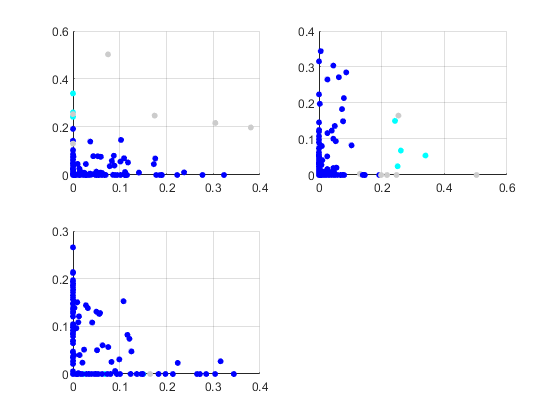

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

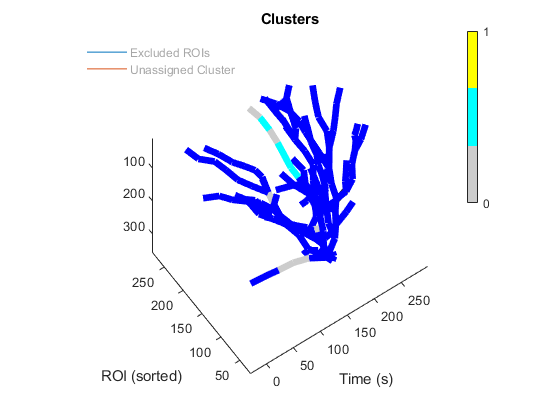

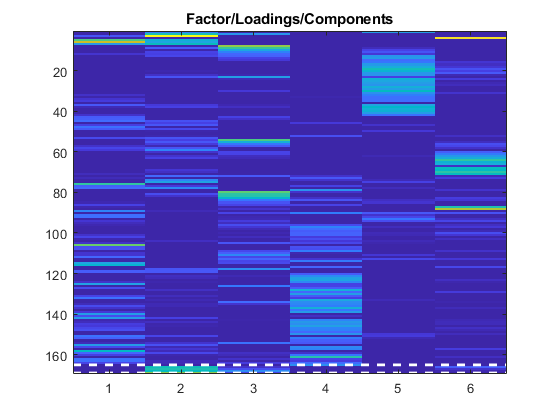

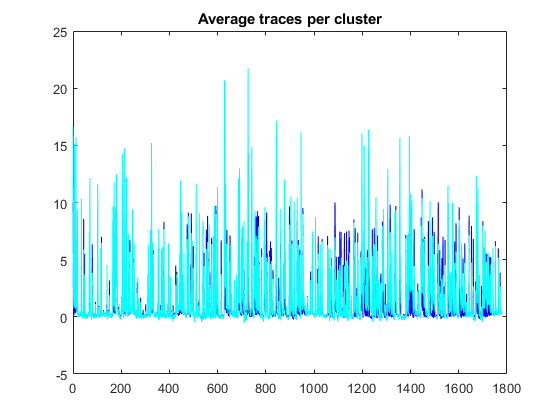

% The second input can control NCluster 
obj.cluster_factors('dbscan', -6);